# **PRACTICE 2. REGRESSION**

## Grado en Ingeniería Informática - Reconocimiento de Patrones

## Fernando M. Quintana Velázquez - Guillermo Bárcena González

# **EXERCISE 1: LINEAR REGRESSION**

**The data in the accompanying table relate heart rate at rest (Y) to kilograms body weight (X).**

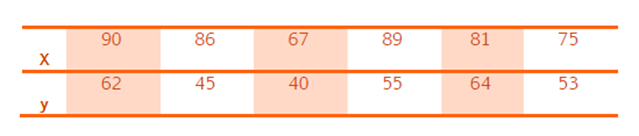

**a) Graph these data. Does exist a linear relationship between body weight and resting heart rate? **

clear all
close all
x=[90,86,67,89,81,75];
y=[62,45,40,55,64,53];
plot(x,y,'o'); hold on;

It doesnt seem like there is a relation.

**b) Compute the regression equation for these data. Then, plot the regression line over the graph of the paragraph a. Interpret the estimated regression coefficients.**

Sx2 = sum(x.*x);
  Sx  = sum(x);
  Sxy = sum(x.*y);
  Sy  = sum(y);

  A = [Sx2      Sx
       Sx   length(y)];

  t = [Sxy
       Sy];

  sol = inv(A)*t;
a = sol(1);  
b = sol(2);
Xi = [1:1:100];
Yi = a*Xi +b; 
plot(Xi,Yi);hold on;


**c) Now examine the value on (67, 40) point . If this data point were removed from the data set, what changes would occur in the estimates of a and b coeficients?**

x=[90,86,89,81,75];
y=[62,45,55,64,53];
Sx2 = sum(x.*x);
  Sx  = sum(x);
  Sxy = sum(x.*y);
  Sy  = sum(y);

  A = [Sx2      Sx
       Sx   length(y)];

  t = [Sxy
       Sy];

  sol = inv(A)*t;
a = sol(1);  
b = sol(2);
Xi = [1:1:100];
Yi = a*Xi +b; 
plot(Xi,Yi);hold on;

If you take this point away it seems like the heart rate is always the same, no matter the weight.

**d) How would you predict the heart rate for a particular subject weighing 70kg?**

prediction = a*70 +b 

prediction = 54.6809

**e) Without doing the computations, which value of X measured would the corresponding Y have the smallest error? Why?**

if its closer to the linear regression line it has the smaller error, because the error is the squared distance to the line. in this case x=89.

**f) What would happen if you apply a polynomial fitting **$\mathit{\mathbf{y}}={\textrm{ax}}^2 +\textrm{bx}+\mathit{\mathbf{c}}$

x = x(:);
y = y(:);
% Vandermonde matrix V
V(:,2+1) = ones(length(x),1,class(x));
for j = 2:-1:1
    V(:,j) = x.*V(:,j+1);
end
res = V\y;
Xi = [1:1:100];
Yi = res(1).*Xi.^2 + res(2).*Xi + res(3); 
plot(Xi,Yi);hold on;

**g) And computing this fitting **$\mathit{\mathbf{y}}={\textrm{ax}}^3 +{\textrm{bx}}^2 +\textrm{cx}+\mathit{\mathbf{d}}$

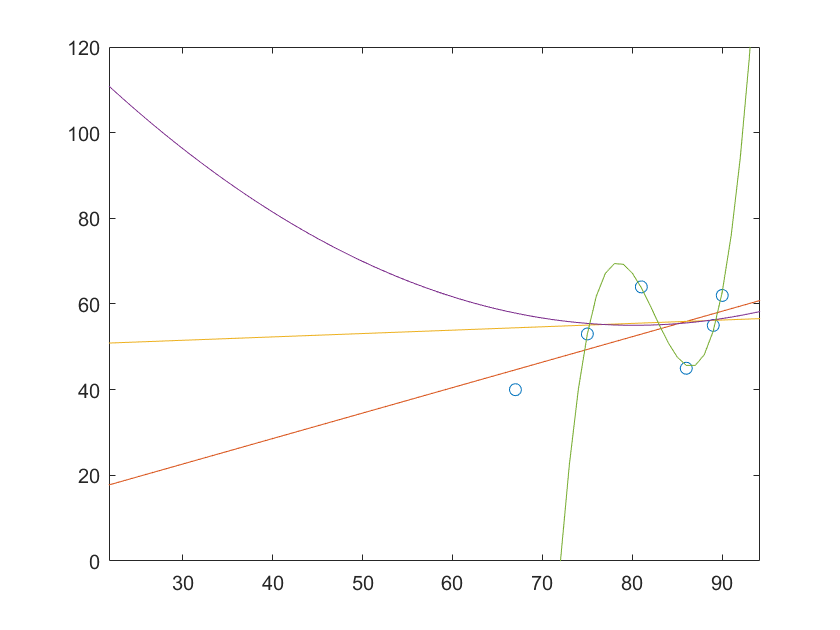

V(:,3+1) = ones(length(x),1,class(x));
for j = 3:-1:1
    V(:,j) = x.*V(:,j+1);
end
res = V\y;
Xi = [1:1:100];
Yi = res(1).*Xi.^3 + res(2).*Xi.^2 + res(3).*Xi+res(4); 
plot(Xi,Yi);hold off;

xlim([21.8 94.2])
ylim([0 120])

**h) Calculate the operation **$\mathbf{y}=\frac{1}{{\mathbf{y}}^2 }$** to obtain a new vector and compute a new fitting **$\mathit{\mathbf{y}}=\mathit{\mathbf{a}}*{\mathit{\mathbf{e}}}^{\textrm{bx}}$

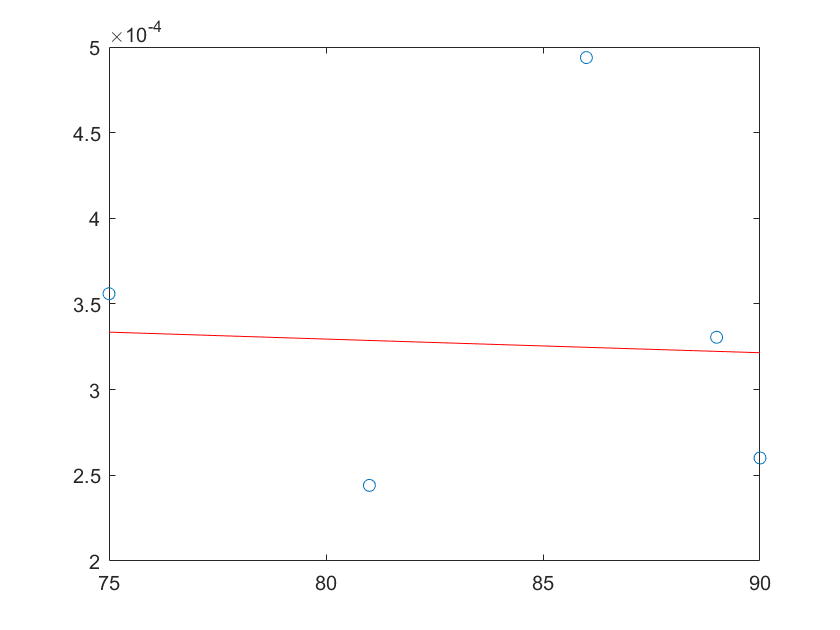

Y5 =1./(y.^2);
Yp = log(Y5);
A = [x ones(size(x))];
sol = inv(A'*A)*(A'*Yp);
B = sol(1);
C = sol(2);

A = exp(C);
figure;

plot(x,Y5,'o');
hold on;
Xp = linspace(min(x),max(x));
Yr = A*exp(B*Xp);

plot(Xp,Yr,'r');
hold off;

**i) Calculate the operation **$\textrm{x2}=\frac{\mathit{\mathbf{x}}}{100}$** ; **$\textrm{y2}=5*\textrm{x2}*{\mathbf{e}}^{4\textrm{x2}}$** and compute a new fitting** $\mathbf{y}=\mathbf{C}*\mathit{\mathbf{x}}*{\mathbf{e}}^{\mathbf{A}\mathbf{x}}$**. What are the values of C and A? Does it seems to C = 5 and A = 4? Why not?**

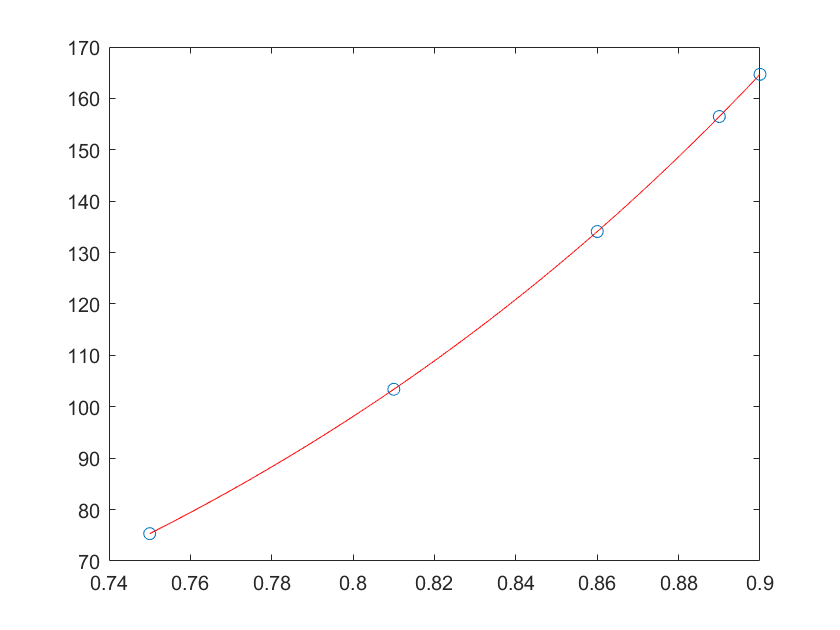

X6 =x/100;
Y6 = 5.*X6.*exp(4*X6);
yp =log(Y6./X6);

A = [X6 ones(size(X6))];
sol = inv(A'*A)*(A'*yp);
B = sol(1);
C = sol(2);

A = exp(C);
plot(X6,Y6,'o');
hold on;

xp = linspace(min(X6),max(X6));
yr = A.*xp.*exp(B*xp);
plot(xp,yr,'r');hold off;

# **EXERCISE 2: POLINOMIAL FUNCTION IN MATLAB**

**a) Calculate the paragraphs b), f), g), h) and i) of the previous exercise using the following MATLAB functions:**

- **polyfit: to calculate polynomial coefficients**

- **polyval: to evaluate polynomials**

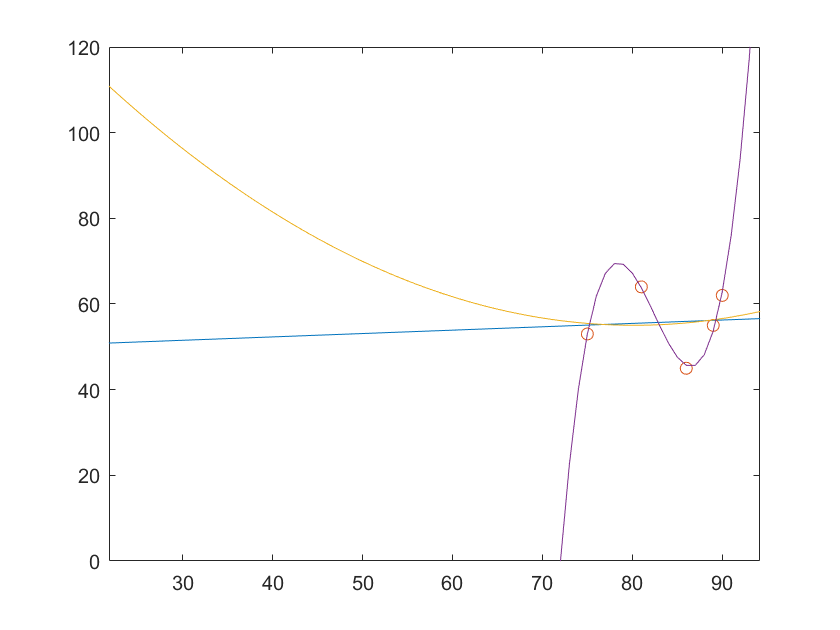

coeff = polyfit(x,y,1);
plot(Xi,polyval(coeff,Xi));hold on;
plot(x,y,'o');
coeffF = polyfit(x,y,2);
plot(Xi,polyval(coeffF,Xi));
coeffG = polyfit(x,y,3);
plot(Xi,polyval(coeffG,Xi));hold off;
xlim([21.8 94.2])
ylim([0 120])

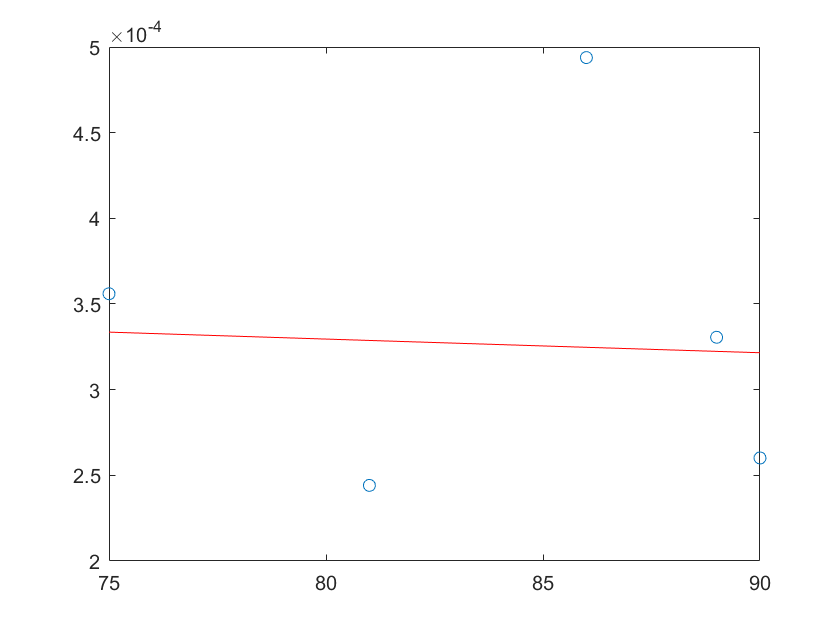

figure

y2 = 1./(y.*y);
P = polyfit(x,log(y2),1);

B = P(1);
C = P(2);
A = exp(C);
xr = linspace(min(x),max(x));
yr = A*exp(B*xr);

figure;
plot(x,y2,'o');hold on;
plot(xr,yr,'r');hold off;

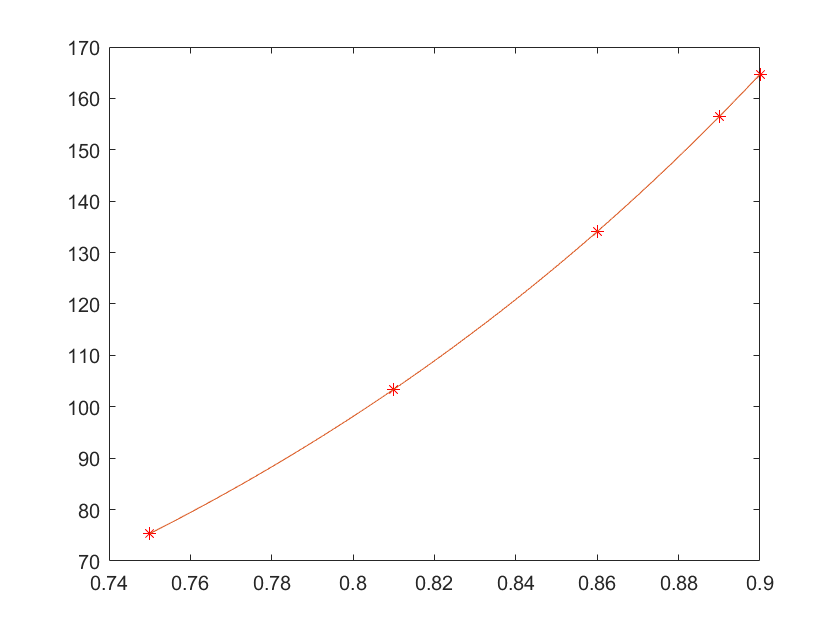

figure
b = log(Y6./X6);
plot(X6,Y6,'r*'); hold on;
p = polyfit(X6,b,1);

xr = linspace(min(X6),max(X6));
yr = polyval(p,xr);
yr = exp(yr);
yr = xr.*yr;
plot(xr,yr); hold off;

**b) Use the function roots to find the polynomial roots in f and g exercises.**

f)

roots(coeffF)

g)

roots(coeffG)